# Regression Analysis

## Prepare the Environment

clc;
clearvars;
close all;

## Load Datasets

% Adjacency matrix
adj = load("Adjacency Matrix/w_adjacency_matrix_by_year.mat");
adj = adj.w_adj_matrix_by_year;

% Migration table
migrationT = load('./Tables/migrationT.mat');
migrationT = migrationT.migrationT;
head(migrationT)

     Country     Code     Year    Emigrants from Albania    Immigrants to Albania    Emigrants from Algeria    Immigrants to Algeria    Emigrants from American Samoa    Immigrants to American Samoa    Emigrants from Andorra    Immigrants to Andorra    Emigrants from Angola    Immigrants to Angola    Emigrants from Anguilla    Immigrants to Anguilla    Emigrants from Armenia    Immigrants to Armenia    Emigrants from Australia    Immigrants to Australia    Emigrants from Austria    Immigrants to Austria    Emigrants from Azerbaijan    Immigrants to Azerbaijan    Emigrants from Bangladesh


% Economy Indicators table
economyT = load('Tables/economyT.mat');
economyT = economyT.economyT;
head(economyT)

     Country     Code     Year    Gini_coeff    Human_Dvpm_Index    Unemployment_Rate    GDP_per_capita    Population    Continent
    _________    _____    ____    __________    ________________    _________________    ______________    __________    _________

    "Albania"    "ALB"    1990     0.22282           0.649               7.2149              4827.1         3.278e+06    "Europe" 
    "Albania"    "ALB"    1995     0.26222           0.632               14.611              4471.6        3.2586e+06    "Europe" 
    "Albania"    "ALB"    2000     0.30163           0.678               19.028              5892.6        3.1661e+06    "Europe" 
    "Albania"    "ALB"    2005     0.3


% Centrality Measures table
centralityT = load('Tables/centralityT.mat');
centralityT = centralityT.centralityT;
head(centralityT)

     Country     Code     Year    In_Degree    Out_Degree    In_Strength    Out_Strength    Betweenness    In_Closeness    Out_Closeness    Eigenvector    Page_Rank       Hubs       Authorities    In_Clustering    Out_Clustering
    _________    _____    ____    _________    __________    ___________    ____________    ___________    ____________    _____________    ___________    _________    __________    ___________    _____________    ______________


% Distance table
distanceT = load('Tables/distanceT.mat');
distanceT = distanceT.distanceT;
head(distanceT)

    Country_Origin     Country_Destination      Code_Origin    Code_Destination    Contig    Smctry    Distance    Language    Colony
    ______________    ______________________    ___________    ________________    ______    ______    ________    ________    ______

      "Albania"       "Angola"                     "ALB"            "AGO"            0         0        5699.6        0          0   
      "Albania"       "United Arab Emirates"       "ALB"            "ARE"            0         0        3722.3        0          0   
      "Albania"       "Armenia"                    "ALB"            "ARM"            0         0        2083.3        0          0   
      "Albania"       "

## Economic Indicators Correlation Study

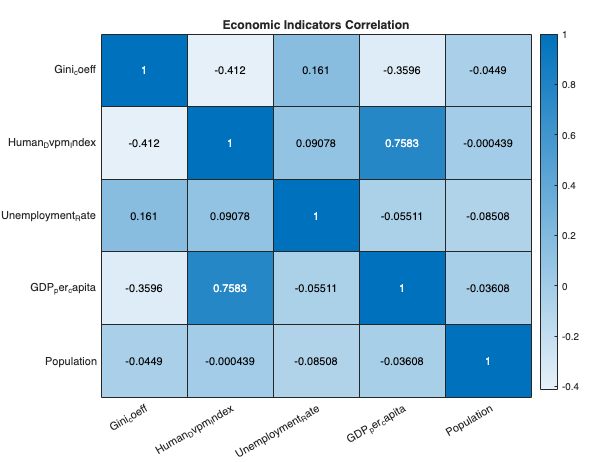

rho = corr(economyT{:, 4:end-1});
varNames = economyT.Properties.VariableNames(4:end-1);

% Display correlation matrix
heatmap(rho, "Title", 'Economic Indicators Correlation', 'XDisplayLabels', varNames, 'YDisplayLabels', varNames)
colorbar

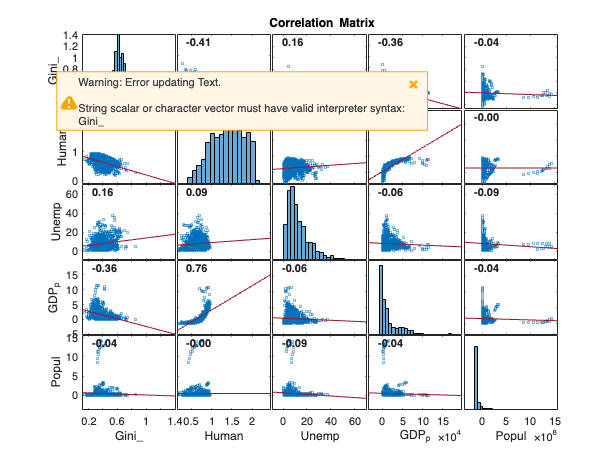


% Show correlation trend
corrplot(economyT(:, 4:end-1))


% Economic indicators correlated at least at the 75%
disp('Highly correlated economic indicators: ')

Highly correlated economic indicators: 


[varNames(any(triu(rho, 1) > 0.75, 1))', varNames(any(triu(rho, 1) > 0.75, 2))]

ans = 1×2 cell array
    {'GDP_per_capita'}    {'Human_Dvpm_Index'}



clearvars("rho", "varNames")

## Data Preparation

### Main Dataset

% Join migration, centrality and economic data in a single table
ECM_T = innerjoin(economyT, centralityT, 'Keys', ["Country", "Code", "Year"]);
ECM_T = innerjoin(ECM_T, migrationT(:, ["Country", "Code", "Year", "Total_Emigrants", "Total_Immigrants"]), 'Keys', ["Country", "Code", "Year"]);
head(ECM_T)

     Country     Code     Year    Gini_coeff    Human_Dvpm_Index    Unemployment_Rate    GDP_per_capita    Population    Continent    In_Degree    Out_Degree    In_Strength    Out_Strength    Betweenness    In_Closeness    Out_Closeness    Eigenvector    Page_Rank       Hubs       Authorities    In_Clustering    Out_Clustering    Total_Emigrants    Total_Immigrants
    _________    _____    ____    __________    ________________    _________________    ______________  

### Dataset Normalization

Normalization of predictors (i.e. economic indicators)

normECM_T = ECM_T;

% Select variables to transform
variables = economyT.Properties.VariableNames(end-3:end-1);

% Apply Log-transform to skewed data distributions
for i = 1:length(variables)
    variable = variables{i};

    % Check 0 presence
    if any(normECM_T.(variable) == 0)
        normECM_T{:, variable} = log(normECM_T.(variable) + 1);
    else
        normECM_T{:, variable} = log(normECM_T.(variable));
    end
end

normECM_T = normalize(normECM_T, "zscore", "robust", "DataVariables", [4 5 6 7 8]);
head(normECM_T)

% Data distribution after transformation and normalization
variables = economyT.Properties.VariableNames(4:end-1)
for i = 1:length(variables)
    variable = variables{i};
    figure;    
    histogram2(normECM_T.(variable), normECM_T.Year)
    title([variable, " data distribution"], 'Interpreter', 'none')    
end

clearvars("variables", "variable", "i")

## Regression Analysis

### Linerar Regression (by year)

#### Centralities as Responses

years = unique(normECM_T.Year);

% Response and predictor variables
responseVariables = centralityT.Properties.VariableNames(8:14);
predictorVariables = economyT.Properties.VariableNames(4:end-1);

% Model matrix
bestLinearModel = zeros(1, length(responseVariables));
worstLinearModel = zeros(1, length(responseVariables));

% Best model matrices
bestModel = zeros(1, length(responseVariables));

for i = 1:length(responseVariables)
    bestLinearRMSE = Inf;
    worstLinearRMSE = 0;
    bestRMSE = Inf;
    response = responseVariables{i};
    disp(['Model fitting for centrality: ', response])
    for j = 1:length(years)
        idx = normECM_T.Year == years(j);
        mdl = fitlm(normECM_T(idx, :), "linear", "ResponseVar", response, ...
            "PredictorVars", predictorVariables);

        if mdl.RMSE < bestLinearRMSE
            bestLinearModel(i) = years(j);
            bestLinearRMSE = mdl.RMSE;
        end

        if mdl.RMSE > worstLinearRMSE
            worstLinearModel(i) = years(j);
            worstLinearRMSE = mdl.RMSE;
        end        
    
        % figure;
        % t = tiledlayout(3, 1, "Padding", "compact");
        % title(t, ['Model Quality in year ', num2str(years(j))])
        % 
        % % Display how the linear regression model fits the data
        % nexttile;
        % plot(mdl)
        % title('Model fitting')
        % 
        % % Display predictor contributions
        % nexttile;
        % bar(mdl.Coefficients.Estimate)
        % set(gca, 'XTickLabel', mdl.CoefficientNames);
        % title('Coefficient values')
        % 
        % % Plot residuals against fitted values
        % nexttile;
        % plotResiduals(mdl, "fitted")
        % title('Residual vs fitted values')

        % Best model through step-wise regression (from linear to polynomial)        
        bestMdl = stepwiselm(normECM_T(idx, :), "linear", "ResponseVar", response, ...
            "PredictorVars", predictorVariables, "Upper", 'poly33333', 'Verbose', 0);        

        if bestMdl.RMSE < bestRMSE
            bestModel(i) = years(j);
            bestRMSE = mdl.RMSE;
        end        
    end
end

clearvars("years", "responseVariables", "predictorVariables", "response", "i", "j", ...
    "idx", "mdl", "t", "bestMdl", "bestLinearRMSE", "worstLinearRMSE", "bestRMSE")

#### Linerar relationship results (centrality)

% Response and predictor variables
responseVariables = centralityT.Properties.VariableNames(8:14);
predictorVariables = economyT.Properties.VariableNames(4:end-1);

bestOfbestLinearIdx = zeros(1, 2);
worstOfworstLinearIdx = zeros(1, 2);
bestOfBestIdx = zeros(1, 2);

bestLinearRMSE = Inf;
worstLinearRMSE = 0;
bestRMSE = Inf;
for i = 1:length(responseVariables)        
    response = responseVariables{i};

    bestLinearYear = bestLinearModel(i);   
    idx = normECM_T.Year == bestLinearYear;    
    mdl = fitlm(normECM_T(idx, :), "linear", "ResponseVar", response, ...
            "PredictorVars", predictorVariables);
    disp(['BEST LINERAR MODEL according to RMSE for centrality ', response, ' is in year ', num2str(bestLinearYear)])
    disp(mdl)

    if mdl.RMSE < bestLinearRMSE
        bestOfbestLinearIdx(1) = i;
        bestOfbestLinearIdx(2) = bestLinearYear;
        bestLinearRMSE = mdl.RMSE;
    end    

    % Plot best linear model
    % figure;
    % t = tiledlayout(3, 1, "Padding", "compact");
    % title(t, ['Model Quality in year ', num2str(bestLinearYear)])
    % 
    % % Display how the linear regression model fits the data
    % nexttile;
    % plot(mdl)
    % title('Model fitting')
    % 
    % % Display predictor contributions
    % nexttile;
    % bar(mdl.Coefficients.Estimate)
    % set(gca, 'XTickLabel', mdl.CoefficientNames);
    % title('Coefficient values')
    % 
    % % Plot residuals against fitted values
    % nexttile;
    % plotResiduals(mdl, "fitted")
    % title('Residual vs fitted values')

    worstLinearYear = worstLinearModel(i);   
    idx = normECM_T.Year == worstLinearYear;    
    mdl = fitlm(normECM_T(idx, :), "linear", "ResponseVar", response, ...
            "PredictorVars", predictorVariables);
    disp(['WORST LINERAR MODEL according to RMSE for centrality ', response, ' is in year ', num2str(worstLinearYear)])
    disp(mdl)

    if mdl.RMSE > worstLinearRMSE
        worstOfworstLinearIdx(1) = i;
        worstOfworstLinearIdx(2) = worstLinearYear;
        worstLinearRMSE = mdl.RMSE;
    end

    % % Plot worst linear model
    % figure;
    % t = tiledlayout(3, 1, "Padding", "compact");
    % title(t, ['Model Quality in year ', num2str(worstLinearYear)])
    % 
    % % Display how the linear regression model fits the data
    % nexttile;
    % plot(mdl)
    % title('Model fitting')
    % 
    % % Display predictor contributions
    % nexttile;
    % bar(mdl.Coefficients.Estimate)
    % set(gca, 'XTickLabel', mdl.CoefficientNames);
    % title('Coefficient values')
    % 
    % % Plot residuals against fitted values
    % nexttile;
    % plotResiduals(mdl, "fitted")
    % title('Residual vs fitted values')

    bestYear = bestModel(i);   
    idx = normECM_T.Year == bestYear;    
    mdl = stepwiselm(normECM_T(idx, :), "linear", "ResponseVar", response, ...
            "PredictorVars", predictorVariables, "Upper", 'poly33333');
    disp(['BEST MODEL according to RMSE for centrality ', response, ' is in year ', num2str(bestYear)])
    disp(mdl)

    if mdl.RMSE < bestRMSE
        bestOfBestIdx(1) = i;
        bestOfBestIdx(2) = bestYear;
        bestRMSE = mdl.RMSE;
    end
    
    % % Plot best model
    % figure;
    % t = tiledlayout(3, 1, "Padding", "compact");
    % title(t, ['Model Quality in year ', num2str(bestYear)])
    % 
    % % Display how the linear regression model fits the data
    % nexttile;
    % plot(mdl)
    % title('Model fitting')
    % 
    % % Display predictor contributions
    % nexttile;
    % bar(mdl.Coefficients.Estimate)
    % set(gca, 'XTickLabel', mdl.CoefficientNames);
    % title('Coefficient values')
    % 
    % % Plot residuals against fitted values
    % nexttile;
    % plotResiduals(mdl, "fitted")
    % title('Residual vs fitted values')
end

clearvars("predictorVariables", "responseVariables", "i", "mdl", "response", ...
    "bestLinearYear", "worstLinearYear", "bestYear", "idx", "t", "bestLinearRMSE", ...
    "worstLinearRMSE", "bestRMSE")

Best and worst models

% Response and predictor variables
responseVariables = centralityT.Properties.VariableNames(8:14);
predictorVariables = economyT.Properties.VariableNames(4:end-1);

disp('Best of best linear models')
response = responseVariables{bestOfbestLinearIdx(1)};
disp([response, ' year ', num2str(bestOfbestLinearIdx(2))])
idx = normECM_T.Year == bestOfbestLinearIdx(2);
mdl = fitlm(normECM_T(idx, :), "linear", "ResponseVar", response, ...
            "PredictorVars", predictorVariables);
disp(mdl)

% % Plot best of best linear model
% figure;
% t = tiledlayout(3, 1, "Padding", "compact");
% title(t, ['Model Quality in year ', num2str(bestOfbestLinearIdx(2))])
% 
% % Display how the linear regression model fits the data
% nexttile;
% plot(mdl)
% title('Model fitting')
% 
% % Display predictor contributions
% nexttile;
% bar(mdl.Coefficients.Estimate)
% set(gca, 'XTickLabel', mdl.CoefficientNames);
% title('Coefficient values')
% 
% % Plot residuals against fitted values
% nexttile;
% plotResiduals(mdl, "fitted")
% title('Residual vs fitted values')

disp('Worst of worst linear models')
response = responseVariables{worstOfworstLinearIdx(1)};
disp([response, ' year ', num2str(worstOfworstLinearIdx(2))])
idx = normECM_T.Year == worstOfworstLinearIdx(2);
mdl = fitlm(normECM_T(idx, :), "linear", "ResponseVar", response, ...
            "PredictorVars", predictorVariables);
disp(mdl)

% Plot best of best linear model
figure;
t = tiledlayout(3, 1, "Padding", "compact");
title(t, ['Model Quality in year ', num2str(worstOfworstLinearIdx(2))])

% Display how the linear regression model fits the data
nexttile;
plot(mdl)
title('Model fitting')

% Display predictor contributions
nexttile;
bar(mdl.Coefficients.Estimate)
set(gca, 'XTickLabel', mdl.CoefficientNames);
title('Coefficient values')

% Plot residuals against fitted values
nexttile;
plotResiduals(mdl, "fitted")
title('Residual vs fitted values')

disp('Best of best models')
response = responseVariables{bestOfBestIdx(1)};
disp([response, ' year ', num2str(bestOfBestIdx(2))])
idx = normECM_T.Year == bestOfBestIdx(2);
mdl = stepwiselm(normECM_T(idx, :), "linear", "ResponseVar", response, ...
            "PredictorVars", predictorVariables, "Upper", 'poly33333');
disp(mdl)

% % Plot best of best linear model
% figure;
% t = tiledlayout(3, 1, "Padding", "compact");
% title(t, ['Model Quality in year ', num2str(bestOfBestIdx(2))])
% 
% % Display how the linear regression model fits the data
% nexttile;
% plot(mdl)
% title('Model fitting')
% 
% % Display predictor contributions
% nexttile;
% bar(mdl.Coefficients.Estimate)
% set(gca, 'XTickLabel', mdl.CoefficientNames);
% title('Coefficient values')
% 
% % Plot residuals against fitted values
% nexttile;
% plotResiduals(mdl, "fitted")
% title('Residual vs fitted values')

clearvars("predictorVariables", "responseVariables", "i", "mdl", "response", ...
    "idx", "t", "bestOfbestLinearIdx", "worstOfworstLinearIdx", "bestOfBestIdx")

#### Total migrants as Responses

years = unique(normECM_T.Year);

% Response and predictor variables
responseVariables = migrationT.Properties.VariableNames(end-1:end);
predictorVariables = economyT.Properties.VariableNames(4:end-1);

% Model matrix
bestLinearModel = zeros(1, length(responseVariables));
worstLinearModel = zeros(1, length(responseVariables));

% Best model matrices
bestModel = zeros(1, length(responseVariables));

for i = 1:length(responseVariables)
    bestLinearRMSE = Inf;
    worstLinearRMSE = 0;
    bestRMSE = Inf;
    response = responseVariables{i};
    disp(['Model fitting for centrality: ', response])
    for j = 1:length(years)
        idx = normECM_T.Year == years(j);
        mdl = fitlm(normECM_T(idx, :), "linear", "ResponseVar", response, ...
            "PredictorVars", predictorVariables, "CategoricalVars", "Continent");

        if mdl.RMSE < bestLinearRMSE
            bestLinearModel(i) = years(j);
            bestLinearRMSE = mdl.RMSE;
        end

        if mdl.RMSE > worstLinearRMSE
            worstLinearModel(i) = years(j);
            worstLinearRMSE = mdl.RMSE;
        end                

        % Best model through step-wise regression (from linear to polynomial)        
        bestMdl = stepwiselm(normECM_T(idx, :), "linear", "ResponseVar", response, ...
            "PredictorVars", predictorVariables, "Upper", 'poly33333', 'Verbose', 0);
        
        if bestMdl.RMSE < bestRMSE
            bestModel(i) = years(j);
            bestRMSE = mdl.RMSE;
        end        
    
        % figure;
        % t = tiledlayout(3, 1, "Padding", "compact");
        % title(t, ['Model Quality in year ', num2str(years(j))])
        % 
        % % Display how the linear regression model fits the data
        % nexttile;
        % plot(mdl)
        % title('Model fitting')
        % 
        % % Display predictor contributions
        % nexttile;
        % bar(mdl.Coefficients.Estimate)
        % set(gca, 'XTickLabel', mdl.CoefficientNames);
        % title('Coefficient values')
        % 
        % % Plot residuals against fitted values
        % nexttile;
        % plotResiduals(mdl, "fitted")
        % title('Residual vs fitted values')
    end
end

clearvars("years", "responseVariables", "predictorVariables", "response", "i", "j", ...
    "idx", "mdl", "t", "bestMdl")

#### Linerar relationship results (migration)

% Response and predictor variables
responseVariables = migrationT.Properties.VariableNames(end-1:end);
predictorVariables = economyT.Properties.VariableNames(4:end-1);

bestOfbestLinearIdx = zeros(1, 2);
worstOfworstLinearIdx = zeros(1, 2);
bestOfBestIdx = zeros(1, 2);

bestLinearRMSE = Inf;
worstLinearRMSE = 0;
bestRMSE = Inf;

for i = 1:length(responseVariables)    
    response = responseVariables{i};

    bestLinearYear = bestLinearModel(i);   
    idx = normECM_T.Year == bestLinearYear;    
    mdl = fitlm(normECM_T(idx, :), "linear", "ResponseVar", response, ...
            "PredictorVars", predictorVariables);
    disp(['BEST LINERAR MODEL according to RMSE for centrality ', response, ' is in year ', num2str(bestLinearYear)])
    disp(mdl)

    if mdl.RMSE < bestLinearRMSE
        bestOfbestLinearIdx(1) = i;
        bestOfbestLinearIdx(2) = bestLinearYear;
        bestLinearRMSE = mdl.RMSE;
    end    

    % Plot best linear model
    figure;
    t = tiledlayout(3, 1, "Padding", "compact");
    title(t, ['Model Quality in year ', num2str(bestLinearYear)])

    % Display how the linear regression model fits the data
    nexttile;
    plot(mdl)
    title('Model fitting')

    % Display predictor contributions
    nexttile;
    bar(mdl.Coefficients.Estimate)
    set(gca, 'XTickLabel', mdl.CoefficientNames);
    title('Coefficient values')

    % Plot residuals against fitted values
    nexttile;
    plotResiduals(mdl, "fitted")
    title('Residual vs fitted values')

    worstLinearYear = worstLinearModel(i);   
    idx = normECM_T.Year == worstLinearYear;    
    mdl = fitlm(normECM_T(idx, :), "linear", "ResponseVar", response, ...
            "PredictorVars", predictorVariables);
    disp(['WORST LINERAR MODEL according to RMSE for centrality ', response, ' is in year ', num2str(worstLinearYear)])
    disp(mdl)

    if mdl.RMSE > worstLinearRMSE
        worstOfworstLinearIdx(1) = i;
        worstOfworstLinearIdx(2) = worstLinearYear;
        worstLinearRMSE = mdl.RMSE;
    end

    % Plot worst linear model
    figure;
    t = tiledlayout(3, 1, "Padding", "compact");
    title(t, ['Model Quality in year ', num2str(worstLinearYear)])

    % Display how the linear regression model fits the data
    nexttile;
    plot(mdl)
    title('Model fitting')

    % Display predictor contributions
    nexttile;
    bar(mdl.Coefficients.Estimate)
    set(gca, 'XTickLabel', mdl.CoefficientNames);
    title('Coefficient values')

    % Plot residuals against fitted values
    nexttile;
    plotResiduals(mdl, "fitted")
    title('Residual vs fitted values')

    bestYear = bestModel(i);   
    idx = normECM_T.Year == bestYear;    
    mdl = stepwiselm(normECM_T(idx, :), "linear", "ResponseVar", response, ...
            "PredictorVars", predictorVariables, "Upper", 'poly33333');
    disp(['BEST MODEL according to RMSE for centrality ', response, ' is in year ', num2str(bestYear)])
    disp(mdl)

    if mdl.RMSE < bestRMSE
        bestOfBestIdx(1) = i;
        bestOfBestIdx(2) = bestYear;
        bestRMSE = mdl.RMSE;
    end
    
    % Plot best model
    figure;
    t = tiledlayout(3, 1, "Padding", "compact");
    title(t, ['Model Quality in year ', num2str(bestYear)])

    % Display how the linear regression model fits the data
    nexttile;
    plot(mdl)
    title('Model fitting')

    % Display predictor contributions
    nexttile;
    bar(mdl.Coefficients.Estimate)
    set(gca, 'XTickLabel', mdl.CoefficientNames);
    title('Coefficient values')

    % Plot residuals against fitted values
    nexttile;
    plotResiduals(mdl, "fitted")
    title('Residual vs fitted values')
end

clearvars("predictorVariables", "responseVariables", "i", "mdl", "response", ...
    "bestLinearYear", "worstLinearYear", "bestYear", "idx", "t", "bestLinearRMSE", ...
    "worstLinearRMSE", "bestRMSE")

Best and worst models

% Response and predictor variables
responseVariables = migrationT.Properties.VariableNames(end-1:end);
predictorVariables = economyT.Properties.VariableNames(4:end-1);

disp('Best of best linear models')
response = responseVariables{bestOfbestLinearIdx(1)};
disp([response, ' year ', num2str(bestOfbestLinearIdx(2))])
idx = normECM_T.Year == bestOfbestLinearIdx(2);
mdl = fitlm(normECM_T(idx, :), "linear", "ResponseVar", response, ...
            "PredictorVars", predictorVariables);
disp(mdl)

% Plot best of best linear model
figure;
t = tiledlayout(3, 1, "Padding", "compact");
title(t, ['Model Quality in year ', num2str(bestOfbestLinearIdx(2))])

% Display how the linear regression model fits the data
nexttile;
plot(mdl)
title('Model fitting')

% Display predictor contributions
nexttile;
bar(mdl.Coefficients.Estimate)
% set(gca, 'XTickLabel', mdl.CoefficientNames);
xticklabels(mdl.CoefficientNames);
title('Coefficient values')

% Plot residuals against fitted values
nexttile;
plotResiduals(mdl, "fitted")
title('Residual vs fitted values')

disp('Worst of worst linear models')
response = responseVariables{worstOfworstLinearIdx(1)};
disp([response, ' year ', num2str(worstOfworstLinearIdx(2))])
idx = normECM_T.Year == worstOfworstLinearIdx(2);
mdl = fitlm(normECM_T(idx, :), "linear", "ResponseVar", response, ...
            "PredictorVars", predictorVariables);
disp(mdl)

% Plot best of best linear model
figure;
t = tiledlayout(3, 1, "Padding", "compact");
title(t, ['Model Quality in year ', num2str(worstOfworstLinearIdx(2))])

% Display how the linear regression model fits the data
nexttile;
plot(mdl)
title('Model fitting')

% Display predictor contributions
nexttile;
bar(mdl.Coefficients.Estimate)
set(gca, 'XTickLabel', mdl.CoefficientNames);
title('Coefficient values')

% Plot residuals against fitted values
nexttile;
plotResiduals(mdl, "fitted")
title('Residual vs fitted values')

disp('Best of best models')
response = responseVariables{bestOfBestIdx(1)};
disp([response, ' year ', num2str(bestOfBestIdx(2))])
idx = normECM_T.Year == bestOfBestIdx(2);
mdl = stepwiselm(normECM_T(idx, :), "linear", "ResponseVar", response, ...
            "PredictorVars", predictorVariables, "Upper", 'poly33333');
disp(mdl)

% Plot best of best linear model
figure;
t = tiledlayout(3, 1, "Padding", "compact");
title(t, ['Model Quality in year ', num2str(bestOfBestIdx)])

% Display how the linear regression model fits the data
nexttile;
plot(mdl)
title('Model fitting')

% Display predictor contributions
nexttile;
bar(mdl.Coefficients.Estimate)
set(gca, 'XTickLabel', mdl.CoefficientNames);
title('Coefficient values')

% Plot residuals against fitted values
nexttile;
plotResiduals(mdl, "fitted")
title('Residual vs fitted values')



clearvars("predictorVariables", "responseVariables", "i", "mdl", "response", ...
    "idx", "t", "bestOfbestLinearIdx", "worstOfworstLinearIdx", "bestOfBestIdx")

### Fixed Effects Regression

#### Centrality as Response

% Response and predictor variables
responseVariables = centralityT.Properties.VariableNames(8:14);

for i = 1:length(responseVariables)
    response = responseVariables{i};
    disp(['Fixed effects model for centrality ', response])

    % Fixed effect model grouped by country and year
    formula = [response, ' ~ Gini_coeff + Human_Dvpm_Index + Unemployment_Rate + GDP_per_capita + Population + (1|Country) + (1|Year)'];
    lme = fitlme(normECM_T, formula);
    
    MSE = lme.MSE;
    R2 = lme.Rsquared.Ordinary;
    Adjusted_R2 = lme.Rsquared.Adjusted;
    F = fitted(lme);
    R = residuals(lme);
    disp(lme);
    disp(['MSE: ', num2str(MSE)])
    disp(['R^2: ', num2str(R2)])    
    disp(['Adjuasted R^2: ', num2str(Adjusted_R2)])

    figure;    
    % Plot Residuals vs Fitted values    
    plot(F,R,'bx')
    xlabel('Fitted Values')
    ylabel('Residuals')
    title('Residual vs fitted values')
    
end

clearvars("responseVariables", "i", "response", "formula", "lme", "R2", ...
    "Adjusted_R2", "MSE", "F", "R")

#### Total Migrants as Response

% Response and predictor variables
responseVariables = migrationT.Properties.VariableNames(end-1:end);

for i = 1:length(responseVariables)
    response = responseVariables{i};
    disp(['Fixed effects model for migration variable ', response])

    % Fixed effect model grouped by country and year
    formula = [response, ' ~ Gini_coeff + Human_Dvpm_Index + Unemployment_Rate + GDP_per_capita + Population + (1|Country) + (1|Year)'];
    lme = fitlme(normECM_T, formula);
    
    MSE = lme.MSE;
    R2 = lme.Rsquared.Ordinary;
    Adjusted_R2 = lme.Rsquared.Adjusted;
    F = fitted(lme);
    R = residuals(lme);
    disp(lme);
    disp(['MSE: ', num2str(MSE)])
    disp(['R^2: ', num2str(R2)])    
    disp(['Adjuasted R^2: ', num2str(Adjusted_R2)])

    figure;    
    % Plot Residuals vs Fitted values    
    plot(F,R,'bx')
    xlabel('Fitted Values')
    ylabel('Residuals')
    title('Residual vs fitted values')
end

clearvars("responseVariables", "i", "response", "formula", "lme", "R2", ...
    "Adjusted_R2", "F", "R", "MSE")

### Gravity Model

#### Data Preparation

Gravity dataset creation

distanceVariables = distanceT.Properties.VariableNames(5:end);
economicVariables = economyT.Properties.VariableNames(4:end-1);

rowNumber = length(unique(migrationT.Country))^2;
colNumber = length(distanceVariables) + length(distanceVariables) + 1;

varTypes = cell(1, colNumber);
varTypes(1:length(distanceVariables)) = {'double', 'double', 'double', 'double', 'double'};
varTypes(1+length(distanceVariables):length(distanceVariables)+length(economicVariables)) = economyT.Properties.VariableUnits(4:end-1);
varTypes(end) = {'double'};

varNames = cell(1, colNumber);
varNames(1:length(distanceVariables)) = distanceVariables;
varNames(1+length(distanceVariables):length(distanceVariables)+length(economicVariables)) = economicVariables;
varNames(end) = {'Migration_Flow'};

% Initialize gratity table
gravityT = table('Size', [rowNumber, colNumber], ...
    'VariableTypes', varTypes, 'VariableNames', varNames);

clearvars("distanceVariables", "economicVariables", "rowNumber", "colNumber", ...
    "varTypes", "varNames")

Add distance variables to the gravity table

distanceVariables = distanceT.Properties.VariableNames(5:end);

% Rearrenge distance matrix values
for i = 1:length(distanceVariables)
    variable = distanceVariables{i};
    P = pivot(distanceT, "Columns", "Country_Destination", "Rows", "Country_Origin", "DataVariable", variable, "RowLabelPlacement", "rownames");
    P = reshape(table2array(P), [], 1);  
    gravityT{:, i} = P;
end

head(gravityT)

    Contig    Smctry    Distance    Language    Colony    Gini_coeff    Human_Dvpm_Index    Unemployment_Rate    GDP_per_capita    Population    Migration_Flow
    ______    ______    ________    ________    ______    __________    ________________    _________________    ______________    __________    ______________

      0         0             0        0          0           0                0                    0                  0               0               0       
      0         0        1511.8        0          0           0                0                    0                  0               0         


clearvars("i", "variable", "P")

#### Distance variables distribution

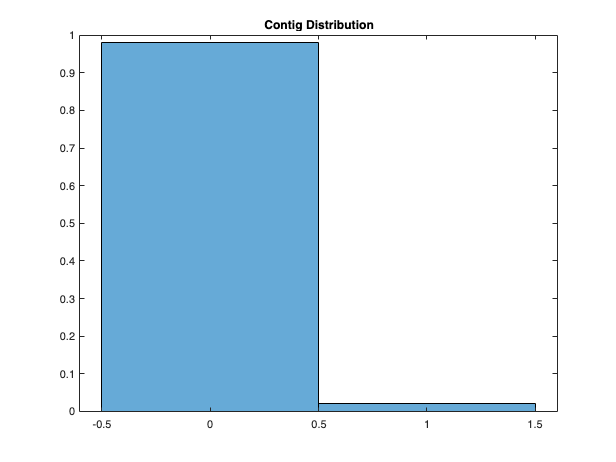

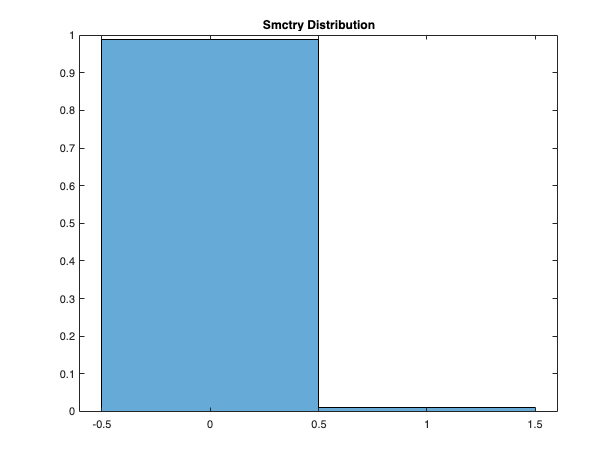

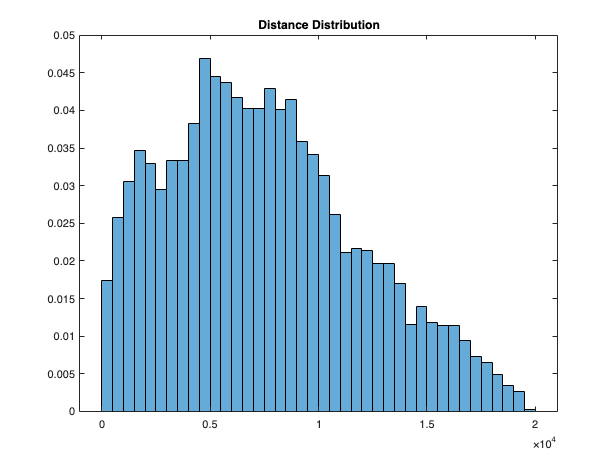

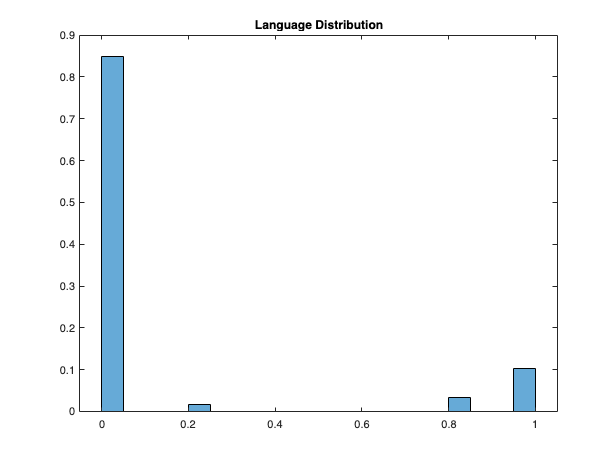

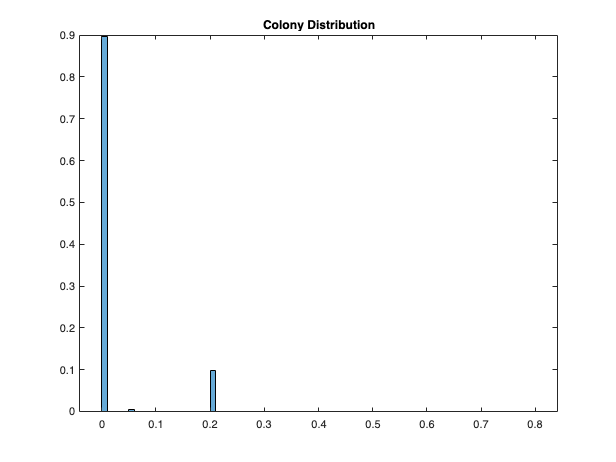

distanceVariables = distanceT.Properties.VariableNames(5:end);

for i = 1:length(distanceVariables)
    variable = distanceVariables{i};
    figure;    
    histogram(gravityT.(variable), 'Normalization', 'probability')
    title([variable, ' Distribution'])
end


% Rescale distance values
nonzeroIdx = gravityT.Distance > 0;
gravityT.Distance(nonzeroIdx) = gravityT.Distance(nonzeroIdx) / 1e4;

clearvars("variable", "i", "distanceVariables", "nonzeroIdx")

#### Data Preparation (economy table)

countries = unique(ECM_T.Country);
numCountries = length(countries);
years = unique(ECM_T.Year);
numYears = length(years);
economyVariables = economyT.Properties.VariableNames(4:end-1);
 
% Matrix initialization
gdp = zeros(numCountries, numCountries, numYears);
hmnDvpm = zeros(numCountries, numCountries, numYears);
gini = zeros(numCountries, numCountries, numYears);
unempl = zeros(numCountries, numCountries, numYears);
pop = zeros(numCountries, numCountries, numYears);
economy = zeros(numCountries*length(economyVariables), numCountries, numYears);

for i = 1:numYears
    year = years(i);
    year_idx = ECM_T.Year == year;    

    for j = 1:numCountries
        % Extract origin variable value
        country = countries(j);
        country_idx = ECM_T.Country == country;
        origin_gdp = ECM_T.GDP_per_capita(country_idx & year_idx);
        origin_humnDvpm = ECM_T.Human_Dvpm_Index(country_idx & year_idx);
        origin_pop = ECM_T.Population(country_idx & year_idx);
        origin_gini = ECM_T.Gini_coeff(country_idx & year_idx);
        origin_unempl = ECM_T.Unemployment_Rate(country_idx & year_idx);

        for k = 1:numCountries
            % Extract destination variable value
            country = countries(k);
            country_idx = ECM_T.Country == country;
            dest_gdp = ECM_T.GDP_per_capita(country_idx & year_idx);
            dest_humnDvpm = ECM_T.Human_Dvpm_Index(country_idx & year_idx);
            dest_pop = ECM_T.Population(country_idx & year_idx);
            dest_gini = ECM_T.Gini_coeff(country_idx & year_idx);
            dest_unempl = ECM_T.Unemployment_Rate(country_idx & year_idx);

            % Update GDP paired matrix
            gdp(j, k, i) = origin_gdp * dest_gdp;            

            % Update Human Development Index paired matrix
            hmnDvpm(j, k, i) = origin_humnDvpm * dest_humnDvpm;

            % Update Population paired matrix
            pop(j, k, i) = origin_pop * dest_pop;

            % Update Gini Coeff paired matrix
            gini(k, j, i) = dest_gini;            

            % Update Unemployment Rate paired matrix            
            unempl(k, j, i) = origin_unempl;
        end

    end
    
end

disp("Paired GDP matrix:")

Paired GDP matrix:


head(gdp)


(:,:,1) =

   1.0e+09 *

    0.0233    0.0426    0.0280    0.0249    0.1491    0.1810    0.0368    0.0084    0.0429    0.1714    0.0304    0.0102    0.0140    0.0214    0.0058    0.0442    0.0502    0.0604    0.0047    0.0057    0.0168    0.1667    0.0088    0.0058    0.0050    0.0468    0.0069    0.0407    0.0141    0.0245    0.0474    0.0210    0.0510    0.1218    0.1138    0.1884    0.0124    0.0300    0.0392    0.0304    0.0251    0.0430    0.0237    0.0037    0.0381    0.1590    0.1634    0.0848    0.0100    0.0538    0.1772    0.0111    0.1171    0.0268    0.0073    0.0096    0.0233    0.0174    0.0189    0.0817    0.1300    0.0088    0.0218    0.0456    0.0360    0.1288    0.1091    0.1766    0.0420    0.1586    0.0392    0.0650    0.0176    0.0249    0.0094    0.0376    0.0061    0.0084    0.0361    0.3420    0.0087    0.0045    0.0512    0.0373    0.0065    0.0779    0.0223    0.0397    0.0790    0.0348    0.0243    0.0199    0.0022    0.0030    0.0300    0.0075    0.1760    

disp("Paired Human Development Index matrix:")

Paired Human Development Index matrix:


head(hmnDvpm)


(:,:,1) =

    0.4212    0.3849    0.1752    0.4270    0.5607    0.5341    0.3797    0.2590    0.4147    0.5283    0.3952    0.2271    0.2644    0.3544    0.3933    0.3810    0.4024    0.4530    0.1791    0.1850    0.2856    0.5588    0.3310    0.2161    0.1327    0.4575    0.3128    0.3985    0.2453    0.3511    0.4277    0.2758    0.4180    0.4757    0.4855    0.5445    0.2044    0.3758    0.4186    0.3680    0.3368    0.4809    0.3544    0.1299    0.4089    0.5263    0.5127    0.3888    0.2096    0.4115    0.5374    0.2888    0.4945    0.3180    0.1752    0.1826    0.3219    0.2862    0.3329    0.4679    0.5413    0.2817    0.3414    0.3978    0.3226    0.4822    0.5069    0.5062    0.4309    0.5491    0.4037    0.4361    0.3115    0.4134    0.2648    0.4751    0.3109    0.1781    0.4803    0.5147    0.2388    0.1941    0.4212    0.3459    0.1532    0.4712    0.2577    0.4024    0.4322    0.4465    0.3758    0.2908    0.1551    0.2161    0.3862    0.2564    0.5497    0.3161    0.13

disp("Paired Gini Coefficient matrix:")

Paired Gini Coefficient matrix:


head(gini)


(:,:,1) =

    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.2228    0.22

disp("Paired Unemployment Rate matrix:")

Paired Unemployment Rate matrix:


head(unempl)


(:,:,1) =

    7.2149   16.8200   16.4790    1.4000    8.4500    3.2500    0.6300    2.1400    0.4200    7.2600    9.6270    1.8720    1.3790    2.8360   16.5890   11.2900    6.0880    6.9000    2.3810    3.1380    9.2440    9.4400   13.8880    5.6010    0.6750    6.1100    2.3700   10.8000    5.3430   19.9760    6.8100    6.4280   11.3430    3.9100    1.9400    9.1700   27.6880    7.1150    4.3970    9.8400    7.1800    1.0290   19.7620    3.1570    4.6370    4.4590    8.0600   16.4400    9.3740    1.8900    4.3200    2.2800    6.2100    2.7400    4.5030    3.0150   12.4420    7.2760    6.1000    7.0600    1.3090    6.8380    2.5100   11.5380    8.9830   16.5200   12.7000   10.8800    6.1600    1.9600   22.5010    0.8000    2.6900    0.9000    2.2890    1.8900   15.3710    2.6640    1.0000    1.0360    6.1720    4.6680    3.6840    0.7950    1.2450    6.3970    9.9020    9.6070    3.0600    0.5530    5.5170   13.4610    2.6510    0.9370   19.4630   10.6180    9.0000    8.1780    1.64

disp("Paired Population matrix:")

Paired Population matrix:


head(pop)


(:,:,1) =

   1.0e+17 *

    0.0001    0.0008    0.0004    0.0001    0.0006    0.0003    0.0002    0.0037    0.0003    0.0003    0.0000    0.0002    0.0000    0.0002    0.0001    0.0000    0.0049    0.0003    0.0003    0.0002    0.0004    0.0009    0.0000    0.0001    0.0002    0.0004    0.0378    0.0011    0.0000    0.0001    0.0001    0.0004    0.0002    0.0000    0.0003    0.0002    0.0000    0.0002    0.0003    0.0019    0.0002    0.0001    0.0000    0.0016    0.0000    0.0002    0.0019    0.0000    0.0000    0.0002    0.0026    0.0005    0.0003    0.0003    0.0002    0.0000    0.0000    0.0002    0.0002    0.0003    0.0000    0.0284    0.0060    0.0019    0.0006    0.0001    0.0002    0.0019    0.0001    0.0040    0.0001    0.0006    0.0008    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0004    0.0003    0.0006    0.0000    0.0003    0.0000    0.0001    0.0000    0.0027    0.0001    0.0001    0.0008    0.0004    0.0013    0.0000    0.0006    0.0005    


economy = [gini; hmnDvpm; unempl; gdp; pop];


clearvars("countries", "numCountries", "years", "numYears", "i", "year", "country", ...
    "year_idx", "country_idx", "j", "k", "origin_humnDvpm", "origin_gdp", "origin_unempl", ...
    "origin_gini", "dest_humnDvpm", "dest_gdp", "dest_gini", "dest_pop", "dest_unempl", ...
    "origin_pop")

#### Model fitting

Model: 

`Flow = [(GDP ⋅ GDP)^α ⋅(HDI ⋅ HDI)^γ ⋅ (1−Gini)^δ ⋅ (1−Population)^λ ⋅ (1−Unemployment)^η)/D^β] ⋅ e^(θ⋅Lang + ϕ⋅Col + ψ⋅Contig + ζ⋅Hist)`

VIF values in year 1990 for each feature:


    1.0482    0.9983    0.2748    0.8710    0.9121    0.1036    0.2366    0.4297    0.8607    1.0094



    "Model for year "    "1990"



Linear regression model:
    log_Migration_Flow ~ 1 + log_Distance + Contig + Smctry + Language + Colony + log_Gini_coeff + log_Human_Dvpm_Index + log_Unemployment_Rate + log_GDP_per_capita + log_Population

Estimated Coefficients:
                             Estimate       SE        tStat       pValue   
                             ________    ________    _______    ___________

    (Intercept)              -17.143      0.48089    -35.648    2.1217e-270
    log_Distance             -2.4117     0.069294    -34.805    3.4308e-258
    Contig                    4.8525      0.12501     38.817    1.5251e-318
    Smctry                    1.9497      0.16917     11.525     1.2135e-30
    Language                  1.2901     0.055995      23.04    4.8853e-116
    Co

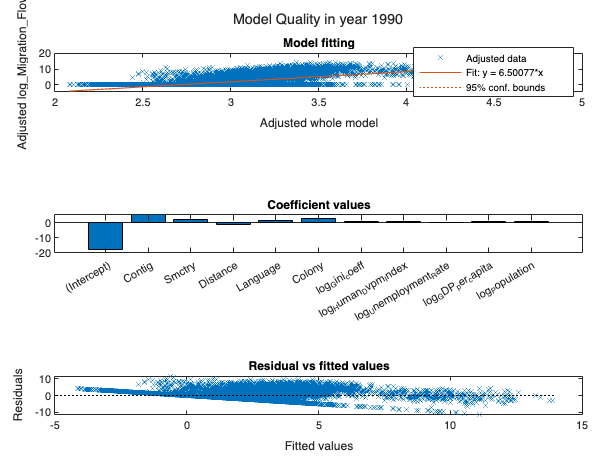

VIF values in year 1995 for each feature:


    0.9947    0.9911    0.2759    0.8694    0.9053    0.0738    0.2292    0.3941    0.8550    1.0101



    "Model for year "    "1995"



Linear regression model:
    log_Migration_Flow ~ 1 + log_Distance + Contig + Smctry + Language + Colony + log_Gini_coeff + log_Human_Dvpm_Index + log_Unemployment_Rate + log_GDP_per_capita + log_Population

Estimated Coefficients:
                             Estimate       SE         tStat       pValue   
                             ________    _________    _______    ___________

    (Intercept)              -18.125       0.53497     -33.88    4.1095e-245
    log_Distance             -2.7267      0.071108    -38.346    3.7261e-311
    Contig                    4.8025       0.12736     37.709    2.7138e-301
    Smctry                    1.9187        0.1724      11.13     1.0811e-28
    Language                  1.2998      0.056849     22.863    2.5477e-114
    

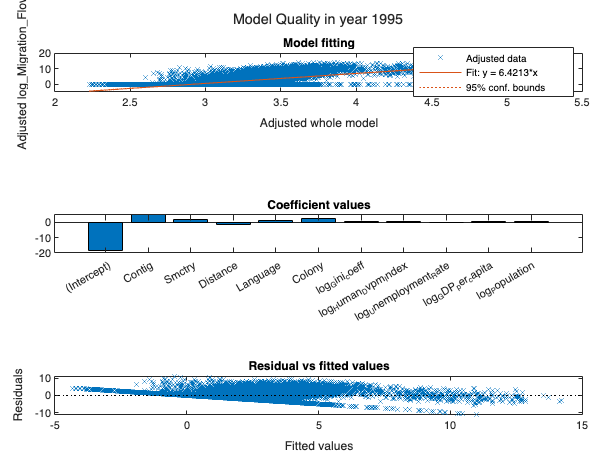

VIF values in year 2000 for each feature:


    0.9953    0.9915    0.2757    0.8697    0.9051    0.0593    0.2123    0.3727    0.8493    1.0099



    "Model for year "    "2000"



Linear regression model:
    log_Migration_Flow ~ 1 + log_Distance + Contig + Smctry + Language + Colony + log_Gini_coeff + log_Human_Dvpm_Index + log_Unemployment_Rate + log_GDP_per_capita + log_Population

Estimated Coefficients:
                             Estimate       SE         tStat       pValue   
                             ________    _________    _______    ___________

    (Intercept)               -16.001      0.61596    -25.977    1.7244e-146
    log_Distance              -2.9013     0.072513     -40.01              0
    Contig                     4.7189      0.12962     36.407    1.3429e-281
    Smctry                      1.818      0.17539     10.365     4.0907e-25
    Language                   1.3729     0.057914     23.705    1.2269e-122
    

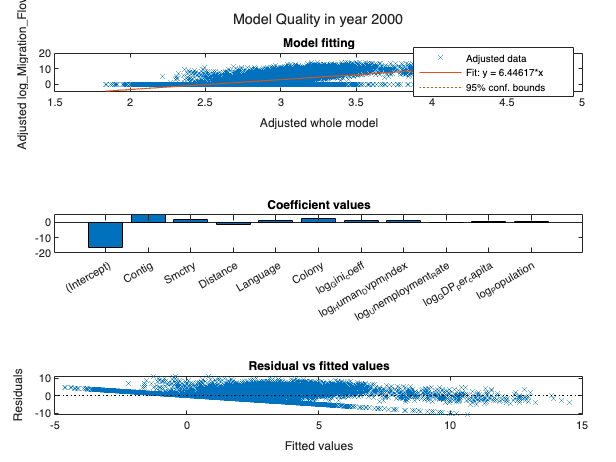

VIF values in year 2005 for each feature:


    0.9960    0.9918    0.2781    0.8698    0.9055    0.0535    0.1941    0.3838    0.8298    1.0099



    "Model for year "    "2005"



Linear regression model:
    log_Migration_Flow ~ 1 + log_Distance + Contig + Smctry + Language + Colony + log_Gini_coeff + log_Human_Dvpm_Index + log_Unemployment_Rate + log_GDP_per_capita + log_Population

Estimated Coefficients:
                             Estimate        SE         tStat       pValue   
                             _________    _________    _______    ___________

    (Intercept)                -17.197      0.67188    -25.595    2.4478e-142
    log_Distance               -2.9003     0.074757    -38.796    3.3514e-318
    Contig                      4.6334      0.13364      34.67    2.9063e-256
    Smctry                      1.9176      0.18088     10.601     3.4093e-26
    Language                     1.484     0.059583     24.906     5.478e-135


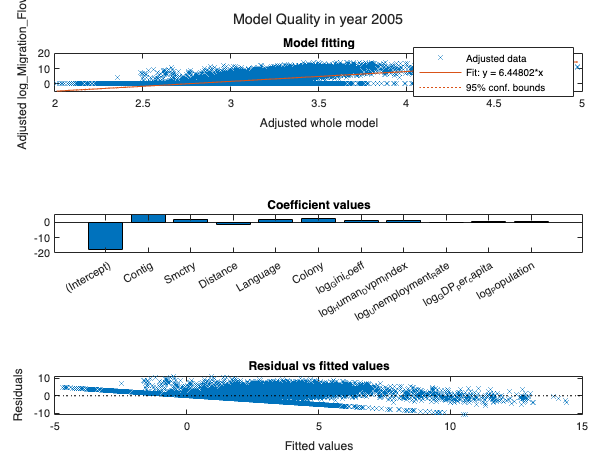

VIF values in year 2010 for each feature:


    0.9989    0.9926    0.2853    0.8722    0.9059    0.0541    0.1799    0.4081    0.7875    1.0098



    "Model for year "    "2010"



Linear regression model:
    log_Migration_Flow ~ 1 + log_Distance + Contig + Smctry + Language + Colony + log_Gini_coeff + log_Human_Dvpm_Index + log_Unemployment_Rate + log_GDP_per_capita + log_Population

Estimated Coefficients:
                             Estimate       SE         tStat       pValue   
                             ________    _________    _______    ___________

    (Intercept)              -18.238       0.76606    -23.808    1.1306e-123
    log_Distance             -2.8945      0.076382    -37.895    3.7109e-304
    Contig                    4.5263       0.13656     33.144    6.2266e-235
    Smctry                     2.052        0.1849     11.098     1.5379e-28
    Language                  1.4984      0.060955     24.581    1.3648e-131
    

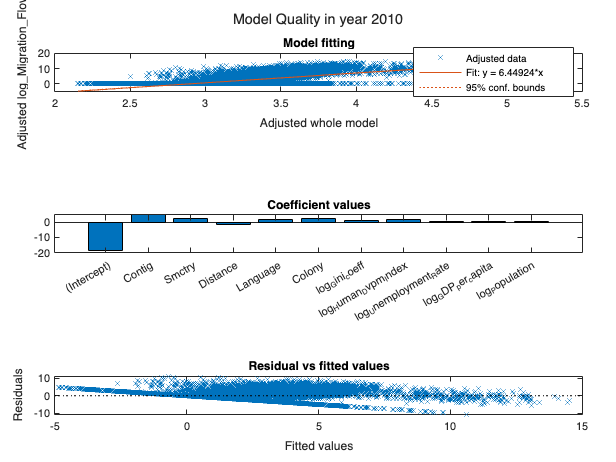

VIF values in year 2015 for each feature:


    0.9984    0.9925    0.2894    0.8733    0.9064    0.0550    0.1592    0.4243    0.7708    1.0110



    "Model for year "    "2015"



Linear regression model:
    log_Migration_Flow ~ 1 + log_Distance + Contig + Smctry + Language + Colony + log_Gini_coeff + log_Human_Dvpm_Index + log_Unemployment_Rate + log_GDP_per_capita + log_Population

Estimated Coefficients:
                             Estimate       SE         tStat       pValue   
                             ________    _________    _______    ___________

    (Intercept)              -18.169       0.85975    -21.133     3.9819e-98
    log_Distance             -2.9382      0.077169    -38.075    6.0038e-307
    Contig                    4.4771       0.13986     32.013    1.1474e-219
    Smctry                    2.0868       0.18946     11.014     3.8846e-28
    Language                  1.5327      0.062548     24.504    8.5514e-131
    

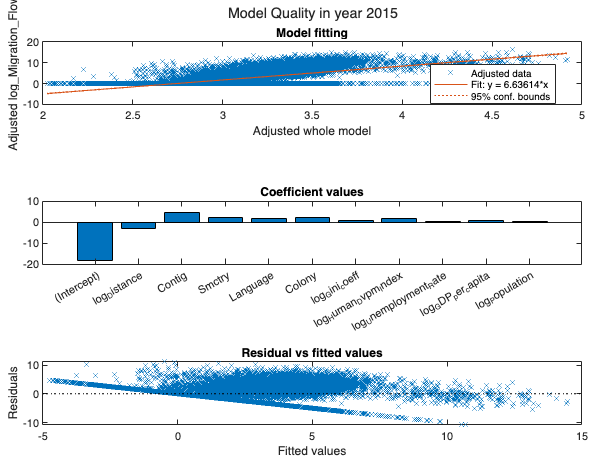

VIF values in year 2020 for each feature:


    0.9982    0.9926    0.2878    0.8721    0.9062    0.0652    0.1466    0.3772    0.7737    1.0107



    "Model for year "    "2020"



Linear regression model:
    log_Migration_Flow ~ 1 + log_Distance + Contig + Smctry + Language + Colony + log_Gini_coeff + log_Human_Dvpm_Index + log_Unemployment_Rate + log_GDP_per_capita + log_Population

Estimated Coefficients:
                             Estimate        SE         tStat        pValue   
                             _________    _________    ________    ___________

    (Intercept)                -18.849      0.93566     -20.145     2.0084e-89
    log_Distance               -3.0565     0.078224     -39.073    1.4822e-322
    Contig                      4.4582      0.14305      31.165    1.4857e-208
    Smctry                      2.0212      0.19396      10.421     2.2961e-25
    Language                    1.6174     0.063913      25.307    3.033

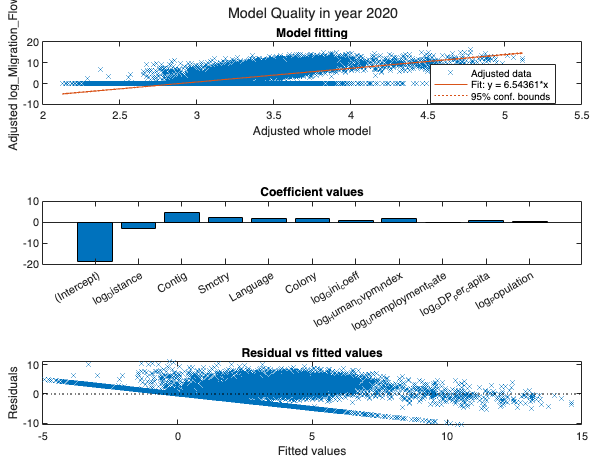

years = unique(migrationT.Year);
countries = unique(migrationT.Country);
economyVariables = economyT.Properties.VariableNames(4:end-1);
distanceVariables = distanceT.Properties.VariableNames(5:end);

% Variance Inflation Factor (VIF)
vif = zeros(1, size(gravityT, 2)-1);

for i = 1:length(years)
    % Update gravity table
    for j = 1:length(economyVariables)
        variable = economyVariables{j};
        startIdx = length(countries) * (j-1) + 1;
        endIdx = length(countries) * j;
        economicValues = reshape(economy(startIdx:endIdx, :, i), [], 1);
        % Check if any value is 0
        if any(economicValues == 0)
            economicValues = economicValues + 1;
        end
        gravityT{:, variable} = economicValues;
    end
    gravityT{:, end} = reshape(adj(:, :, i), [], 1) + 1;    % +1 to avoid log(0) for next log-transform

    % Check for feature collinearity    
    for j = 1:size(gravityT, 2)-1                
        response = gravityT.Properties.VariableNames{j};        
        mdl = fitlm(gravityT, "ResponseVar", response); 
        r2 = mdl.Rsquared.Ordinary;
        vif(j) = 1 / (1 - r2);
    end
    
    % Display VIF values
    disp(['VIF values in year ', num2str(years(i)), ' for each feature:']);
    disp(vif);    

    distance = gravityT.Distance;
    if any(distance == 0)
        distance = distance + 1;
    end    
    % Log transformation for log-linear regression
    logGravityT = [array2table(log(distance), "VariableNames", "log_Distance"), gravityT(:, 1:length(distanceVariables)), varfun(@log, gravityT(:, length(distanceVariables)+1:end))];
    logGravityT.Distance = [];
    mdl_table = [logGravityT(:, vif < 7), logGravityT(:, "log_Migration_Flow")];
    mdl = fitlm(mdl_table, "ResponseVar", "log_Migration_Flow");
    disp(["Model for year ", num2str(years(i))])
    disp(mdl)

    figure;
    t = tiledlayout(3, 1, "Padding", "compact");
    title(t, ['Model Quality in year ', num2str(years(i))])
    
    % Display how the linear regression model fits the data
    nexttile;
    plot(mdl)
    title('Model fitting')
    
    % Display predictor contributions
    nexttile;
    bar(mdl.Coefficients.Estimate)
    set(gca, 'XTickLabel', mdl.CoefficientNames);
    title('Coefficient values')
    
    % Plot residuals against fitted values
    nexttile;
    plotResiduals(mdl, "fitted")
    title('Residual vs fitted values')
    fprintf("\n\n")
end


clearvars("years", "economyVariables", "vif", "i", "j", "variable", "startIdx", ...
    "endIdx", "response", "mdl", "r2", "mdl_table", "countries", "distanceVariables", ...
    "logGravityT", "economicValues", "t")

### Panel Vector Autoregression

Need for more data to perform Panel Vector Autoregression

#### Data transformation (using price2ret and diff)

Variant to normECM_T table

% countries = unique(ECM_T.Country);
% rows = size(ECM_T, 1) - length(countries);
% cols = size(ECM_T, 2);
% 
% Initialize table with transformed data
% trans_ECM_T = table('Size', [rows, cols], 'VariableTypes', ECM_T.Properties.VariableUnits, 'VariableNames', ECM_T.Properties.VariableNames);
% 
% Select variables to transform
% variables = ECM_T.Properties.VariableNames(4:end);
% unif_norm_variables = {'Gini_coeff', 'Human_Dvpm_Index', 'Out_Closeness'};  % Response variables having a gaussian distribution
% exp_variables = setdiff(variables, unif_norm_variables);                    % Response variables having an exponantial distribution
% 
% for i = 1:length(countries)
%     country = countries{i};
%     skip = sum(ECM_T.Country == country);
% 
%     Retrieve Country, Code and Year
%     country_start_idx = (i -1) * skip + 2;     % increment by 2 to skip 1st row
%     country_end_idx = i * skip;
%     CCY = ECM_T(country_start_idx:country_end_idx, 1:3);
%     CCY.Country = categorical(CCY.Country);
%     CCY.Code = categorical(CCY.Code);
% 
%     Compute data position
%     start_idx = (i -1) * (skip - 1) + 1;
%     end_idx = i * (skip - 1);
% 
%     Rewrite Country, Code and Year skipping 1st row
%     trans_ECM_T(start_idx:end_idx, 1:3) = CCY;
% 
%     Difference of the logarithms to counter exponential growth
%     for j = 1:length(exp_variables)
%         variable = exp_variables{j};
%         variable_percent = price2ret(ECM_T.(variable)((country_start_idx-1):country_end_idx));
%         trans_ECM_T{start_idx:end_idx, variable} = variable_percent;
%     end
% 
%     Stabilize taking first difference
%     for j = 1:length(unif_norm_variables)
%         variable = unif_norm_variables{j};
%         variable_1st_diff = diff(ECM_T.(variable)((country_start_idx-1):country_end_idx));
%         trans_ECM_T{start_idx:end_idx, variable} = variable_1st_diff;
%     end
% end
% 
% Data distribution after transformation
% exp_variables = trans_ECM_T.Properties.VariableNames(4:end);
% for i = 1:length(exp_variables)
%     variable = exp_variables{i};
%     figure;   
%     histogram2(trans_ECM_T.(variable), trans_ECM_T.Year)
%     title([variable, " data distribution"])
% end
% 
% Scale variables to similar values
% trans_ECM_T.Betweenness = trans_ECM_T.Betweenness/1e19;
% trans_ECM_T.Gini_coeff = trans_ECM_T.Gini_coeff * 2;
% trans_ECM_T.Human_Dvpm_Index = trans_ECM_T.Human_Dvpm_Index * 2;
% trans_ECM_T.Population = trans_ECM_T.Population * 2;
% trans_ECM_T.Out_Closeness = trans_ECM_T.Out_Closeness * 2;
% 
% clearvars("countries", "rows", "cols", "variables", "unif_norm_variables", "i", ...
%     "country", "skip", "country_start_idx", "country_end_idx", "start_idx", ...
%     "end_idx", "j", "variable", "variable_1st_diff", "variable_percent", "CCY")

#### Test for stationarity

% variables = ECM_T.Properties.VariableNames(4:end);
% 
% Unit root test
% for i = 1:length(variables)
%     variable = variables{i};
%     display(['Dickey-Fuller test for variable: ', variable])
%     h = adftest(normECM_T(:, 4:end), "DataVariable", variable)
%     if ~h.h
%         display(['Impossible to reject the hypothesis of no unit root for reponse variable: ', variable])
%         h.h
%         h.pValue
%     end
% end
% 
% clearvars("variables", "i", "h", "variable")

#### Test for cointagration

% variables = ECM_T.Properties.VariableNames(4:end);
% 
% Unit root test
% for i = 1:length(variables)
%     variable = variables{i};
%     display(['Engle-Granger cointegration test for variable: ', variable])
%     h = egcitest(normECM_T(:, 4:end), "ResponseVariable", variable)
%     if ~h.h
%         display(['Impossible to reject the hypothesis of no cointegration for response variable: ', variable])
%         h.h
%         h.pValue
%     end
% end
% 
% clearvars("variables", "i", "h", "variable")

#### Optimal Lag length

N.B.: Needed more data. Too few data per country implies to build unconsistent response time series. Run only if dataset is large enough

% countries = unique(normECM_T.Country);
% numseries = length(normECM_T.Properties.VariableNames(4:end));
% 
% % Model definitions
% Mdl(1) = varm(numseries, 1);
% Mdl(2) = varm(numseries, 2);
% Mdl(3) = varm(numseries, 3);
% Mdl(4) = varm(numseries, 4);
% Mdl(5) = varm(numseries, 5);
% Mdl(6) = varm(numseries, 6);
% 
% numCountries = length(countries);
% numMdl = numel(Mdl);
% logL = zeros(numMdl,1);      % Preallocate
% numParam = zeros(numMdl,1);
% numObs = zeros(numMdl,1);
% 
% % Determine logL and parameter counts 
% for i = 1:numCountries
%     idx = normECM_T.Country == countries(i);
%     countryData = normECM_T(idx, :);
% 
%     for j = 1:numMdl
%     y0 = countryData(1:Mdl(j).P, 4:end);             % Presample
%     yest = countryData((Mdl(j).P+1):end, 4:end);     % Estimation sample
%     [EstMdl,~,logL(j)] = estimate(Mdl(j),yest,"Presample",y0,...
%         Display="off");
%     results = summarize(EstMdl);
%     numParam(j) = results.NumEstimatedParameters;
%     numObs(j) = results.SampleSize; 
%     end
% end
% 
% % Compute the normalized aic for each model
% aic = aicbic(logL,numParam,numObs,Normalize=true)
% 
% % Determine the model that yields the minimum AIC
% [~,minIdx] = min(aic);
% Mdl(minIdx).Description

## Bayesian Panel VAR (BEAR Toolbox)

Problem in the source code (untrusted library)

### Store data in .xls file

% countries = unique(normECM_T.Country);
% 
% filename = 'MEC.xlsx';
% for i = 1:length(countries)
%     Extract country info
%     country = countries(i);    
%     idx = normECM_T.Country == country;    
%     countryData = normECM_T(idx, :);    
% 
%     Delete non-numerical values
%     countryData.Country = [];
%     countryData.Code = [];
% 
%     Do not consider centrality measures
%     countryData(:, 9:end) = [];
% 
%     Add 'y' character at the end of Year units
%     countryData.Properties.VariableUnits{1} = 'string';
%     Year = varfun(@(x) x+"y", countryData, "InputVariables", "Year"); 
%     countryData.Year = countryData.Year + "y";
% 
%     Replace white spaces with underscore
%     country = strrep(country, ' ', '_');
% 
%     writetable(countryData, filename, "Sheet", country, "FileType", "spreadsheet", "PreserveFormat", false);
% end
% 
% clearvars("countries", "filename", "i", "country", "idx", "countryData")

### Add restrictions to shocks and their periodicity

% variables = normECM_T.Properties.VariableNames(4:end-5);
% shocks = variables(1:7);
% shockLabels = shocks;
% for i = 1:length(shocks)    
%     shockLabels{i} =  [shockLabels{i}, '_Shock'];
% end
% 
% Define the restrictions
% '+' for positive, '-' for negative, '0' for no response, '[min max]' for range
% restrictions = {
%     '+'     '-'     '+'     '-'     '+'     '-'     '-';  % Total_Emigrants
%     '-'     '+'     '-'     '+'     '-'     '+'     '+';  % Total_Immigrants
%     '0'     '0'     '+'     '-'     '+'     '+'     '-';  % Gini_coeff
%     '0'     '0'     '-'     '+'     '-'     '+'     '+';  % Human_Dvpm_Index
%     '0'     '0'     '+'     '-'     '+'     '-'     '-';  % Unemployment_Rate
%     '0'     '0'     '-'     '+'     '-'     '+'     '+';  % GDP_per_capita
%     '0'     '0'     '-'     '+'     '-'     '+'     '+';  % Population    
% };
% 
% Restrictions table
% signResValuesTable = array2table(restrictions, 'VariableNames', shocks, 'RowNames', variables);
% 
% Define the period for restriction application
% periodicity = cell(length(variables), length(shocks));
% period = {"0 6"};
% periodicity(:, :) = period;
% 
% Periodicity table
% signResPeriodsTable = array2table(periodicity, 'VariableNames', shocks, 'RowNames', variables);
% 
% Rel magn values table
% relResValuesTable = table('Size', [length(variables), length(variables)], 'VariableTypes', ECM_T.Properties.VariableUnits(4:end-5), 'VariableNames', shocks, 'RowNames', variables);
% 
% Rel magn periodicity table
% relResPeriodsTable = table('Size', [length(variables), length(variables)], 'VariableTypes', ECM_T.Properties.VariableUnits(4:end-5), 'VariableNames', shocks, 'RowNames', variables);
% 
% FEDV values table
% FEDVResValuesTable = table('Size', [length(variables), length(variables)], 'VariableTypes', ECM_T.Properties.VariableUnits(4:end-5), 'VariableNames', shocks, 'RowNames', variables);
% 
% FEDV periodicity table
% FEDVResPeriodsTable = table('Size', [length(variables), length(variables)], 'VariableTypes', ECM_T.Properties.VariableUnits(4:end-5), 'VariableNames', shocks, 'RowNames', variables);
% 
% Write to the 'sign res values' worksheet in the Excel file
% filename = 'MEC.xlsx';
% Shock labels
% writecell(shockLabels, filename, 'Sheet', 'sign res values', 'Range', 'B1');
% writecell(shockLabels, filename, 'Sheet', 'sign res periods', 'Range', 'B1');
% writecell(shockLabels, filename, 'Sheet', 'relmagn res values', 'Range', 'B1');
% writecell(shockLabels, filename, 'Sheet', 'relmagn res periods', 'Range', 'B1');
% writecell(shockLabels, filename, 'Sheet', 'FEDV res values', 'Range', 'B1');
% writecell(shockLabels, filename, 'Sheet', 'FEDV res periods', 'Range', 'B1');
% Shock restrictions
% writetable(signResValuesTable, filename, 'Sheet', 'sign res values', 'WriteRowNames', true, 'Range', 'A2');
% Restriction periodicity
% writetable(signResPeriodsTable, filename, 'Sheet', 'sign res periods', 'WriteRowNames', true, 'Range', 'A2');
% Rel magn values
% writetable(relResValuesTable, filename, 'Sheet', 'FEDV res values', 'WriteRowNames', true, 'Range', 'A2');
% Rel magn periods
% writetable(relResPeriodsTable, filename, 'Sheet', 'FEDV res periods', 'WriteRowNames', true, 'Range', 'A2');
% FEDV values
% writetable(FEDVResValuesTable, filename, 'Sheet', 'FEDV res values', 'WriteRowNames', true, 'Range', 'A2');
% FEDV periods
% writetable(FEDVResPeriodsTable, filename, 'Sheet', 'FEDV res periods', 'WriteRowNames', true, 'Range', 'A2');
% 
% clearvars("variables", "shocks", "shockLabels", "restrictions", "signResTable", ...
%     "filename")

### Model fitting

#### Settings

% filename = 'MEC.xlsx';
% endoVariables = normECM_T.Properties.VariableNames(4:end-5);
% units = unique(normECM_T.Country);
% 
% s = BEARsettings('PANEL', 'Excel', filename);
% s.frequency = 1;                                % data frequency (1=yearly, 2= quarterly, 3=monthly, 4=weekly, 5=daily, 6=undated)
% s.startdate = '1990y';                          
% s.enddate = '2020y';                            
% s.varendo = '';                                 % endogenous variables
% for i = 1:length(endoVariables)
%     variable = endoVariables{i};   
%     s.varendo = [s.varendo, variable, ' '];
% end
% s.varendo = strip(s.varendo);
% s.varexo = '';                                  % exogenous variables
% s.lags = 1;                                     % number of lags
% s.const = true;                                 % inclusion of a constant 
% s.results_path = './';                          % path where there results file is stored
% s.results_sub = 'bayesian_panel_var';           % name of the results file
% s.results = true;                               % save the results in the excel file
% s.plot = true;                                  % plot the results
% s.workspace = false;                            % save the workspace as a .mat file
% s.excelFile = filename;                         % Excel file used for the inputs
% s.unitnames = '';                               % Panel units
% for i = 1:length(units)
%     unit = strrep(units(i), ' ',  '_');
%     unit = convertStringsToChars(unit);
%     s.unitnames = [s.unitnames, unit, ' '];
% end
% s.unitnames = strip(s.unitnames);
% 
% Model options
% s.IRF=1;                                        % activate impulse response functions
% s.F=0;                                          % activate unconditional forecasts
% s.FEVD=0;                                       % activate forecast error variance decomposition
% s.HD=0;                                         % activate historical decomposition
% s.CF=0;                                         % activate conditional forecasts
% s.IRFt=4;                                       % structural identification (1=none, 2=Choleski, 3=triangular factorisation, 4=sign restrictions)
% s.Feval=0;                                      % activate forecast evaluation
% s.CFt=1;                                        % type of conditional forecasts (1=standard (all shocks), 2=standard (shock-specific), 3=tilting (median), 4=tilting (interval))
% s.IRFperiods = 20;                              % number of periods for impulse response functions
% s.Fendsmpl=1;                                   % start forecasts immediately after the final sample period
% s.hstep=1;                                      % step ahead evaluation
% 
% s.panel="Pooled";                               %Type of panel ('Mge', 'Pooled', 'Random_zh', 'Random_hierarchical', 'Factor_static', or 'Factor_dynamic')
% 
% s.ar=0.8;
% s.lambda1=0.1;
% s.lambda2=0.5;
% s.lambda3=1;
% s.lambda4=100;
% 
% s.It=2000;                                      % total number of iterations for the Gibbs sampler
% s.Bu=1000;                                      % number of burn-in iterations for the Gibbs sampler
% s.pick=0;                                       % choice of retaining only one post burn iteration over 'pickf' iterations
% s.pickf=20;                                     % frequency of iteration picking (e.g. pickf=20 implies that only 1 out of 20 iterations will be retained)
% s.s0=0.001;                                     % hyperparameter: autoregressive coefficient
% s.v0=0.001;                                     % hyperparameter: v0
% s.alpha0=1000;                                  % hyperparameter: alpha0
% s.delta0=1;                                     % hyperparameter: delta0
% s.gamma=0.85;                                   % hyperparameter: gama
% s.a0=1000;                                      % hyperparameter: a0
% s.b0=1;                                         % hyperparameter: b0
% s.rho=0.75;                                     % hyperparameter: rho
% s.psi=0.1;                                      % hyperparameter: psi
% 
% s.window_size=0;                                % window_size for iterative forecasting 0 if no iterative forecasting
% s.evaluation_size=0.5;                          % evaluation_size as percent of window_size
% s.cband=0.66;                                   % confidence/credibility level for VAR coefficients
% s.IRFband=0.66;                                 % confidence/credibility level for impusle response functions
% s.Fband=0.66;                                   % confidence/credibility level for forecasts
% s.FEVDband=0.66;                                % confidence/credibility level for forecast error variance decomposition
% s.HDband=0.66;                                  % confidence/credibility level for historical decomposition
% 
% disp(s)
% 
% clearvars("filename", "endoVariables", "units", "unit", "variable", "i")

#### Model

% BEARmain(s)